global pt1 pt06 pt03 pt01 pt003 
load("experimental_data.mat")

warning('off')
x0_ =[0.00240513591275915 2.28172994869030	5.27128903451110	0.118256569883563	0.116899888251102	25.7008548044007 0.314607561605940	1.56022635419334	26.4516608807189];

MU  = x0_(1);
ALPHA = x0_(2);
KELAS = x0_(3);
MUVIS = x0_(4);
ALPHAVIS = x0_(5);
KVIS = x0_(6);
RTIME = x0_(7);
MUVIS_2 = MUVIS;
ALPHAVIS_2 = ALPHAVIS;
KVIS_2 = KVIS;
RTIME_2 = x0_(8);
MUVIS_3 = MUVIS;
ALPHAVIS_3 = ALPHAVIS;
KVIS_3 = KVIS;
RTIME_3 = x0_(9);
% 
x0=[MU, ALPHA, KELAS, MUVIS, ALPHAVIS, KVIS, RTIME,  RTIME_2, RTIME_3];
global xsol
xsol = zeros(size(x0));
A = [];
b = [];
Aeq = [];
beq = [];
lb = zeros(1, 15);
ub = [];
nonlcon = [];
penalty = 1e10;
f1 = @loss_function_lsq_3ELred_NR;
f2 = @constraint3ELred;
loss_function_lsq_cstr = @(x) f1(x) + penalty * f2(x);

options = optimset('PlotFcns',@optimplotfval, 'MaxIter', 100, 'Display','iter');
[x,fval,exitflag,output] = lsqnonlin(loss_function_lsq_cstr, x0, lb, ub, options)

global DFGRD0 STRETCH_NEW STATEV DTIME ...
MU  ALPHA  KELAS  ...


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0         10         6502.87                      2.24e+04
     1         20         479.483       0.795684       2.05e+03      
     2         30         222.218       0.535735            218      
     3         40          110.44        3.20065       3.32e+03      
     4         50         93.8461     0.00346868           83.1      
     5         60         83.9389        1.61222       1.32e+05      
     6         70         83.9389       0.403056       1.32e+05      
     7         80         81.6635       0.100764       1.52e+04      
     8         90         81.6337       0.100764       1.28e+04      
     9        100         81.2065       0.025191       5.56e+03      
    10        110         81.2065       0.025191       5.56e+03      
    11        120          81.082     0.00629775       2.46e+03      
    12        130         77.052

MUVIS ALPHAVIS  KVIS ETADEV ETAVOL ...
MUVIS_2 ALPHAVIS_2  KVIS_2  ETADEV_2 ETAVOL_2  ...
MUVIS_3 ALPHAVIS_3 KVIS_3 ETADEV_3 ETAVOL_3
optionsNR = optimoptions('fsolve','Display', 'none','FunctionTolerance', 1e-16, 'StepTolerance', 1e-16);

MU  = x(1);
ALPHA = x(2);
KELAS = x(3);
MUVIS = x(4);
ALPHAVIS = x(5);
KVIS = x(6);
RTIME = x(7);
ETADEV = RTIME * MUVIS * ALPHAVIS;
ETAVOL = RTIME * KVIS;
MUVIS_2 = x(8);
ALPHAVIS_2 = x(9);
KVIS_2 = x(10);
RTIME_2 = x(11);
ETADEV_2 = RTIME_2 * MUVIS_2 * ALPHAVIS_2;
ETAVOL_2 = RTIME_2 * KVIS_2;

MUVIS_3 = x(12);
ALPHAVIS_3 = x(13);
KVIS_3 = x(14);
RTIME_3 = x(15);
ETADEV_3 = RTIME_3 * MUVIS_3 * ALPHAVIS_3;
ETAVOL_3 = RTIME_3 * KVIS_3;


% loss for strain rate pt1
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt1 = size(pt1);
lenpt1 = lenpt1(1);
pt1sim = zeros(lenpt1, 2);
pt1sim(1,:) = [1, 0];
for datapoint = 2:lenpt1
    STRETCH_NEW = pt1(datapoint, 2);
    DTIME = pt1(datapoint, 4) - pt1(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN_3EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                         MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2, ...
                                                         MUVIS_3, ALPHAVIS_3, KVIS_3, ETADEV_3, ETAVOL_3);

    DFGRD0 = DFGRD1;
    pt1sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt06
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt06 = size(pt06);
lenpt06 = lenpt06(1);
pt06sim = zeros(lenpt06, 2);
pt06sim(1,:) = [1, 0];
for datapoint = 2:lenpt06
    STRETCH_NEW = pt06(datapoint, 2);
    DTIME = pt06(datapoint, 4) - pt06(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN_3EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                         MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2, ...
                                                         MUVIS_3, ALPHAVIS_3, KVIS_3, ETADEV_3, ETAVOL_3);

    DFGRD0 = DFGRD1;
    pt06sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt03
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt03 = size(pt03);
lenpt03 = lenpt03(1);
pt03sim = zeros(lenpt03, 2);
pt03sim(1,:) = [1, 0];
for datapoint = 2:lenpt03
    STRETCH_NEW = pt03(datapoint, 2);
    DTIME = pt03(datapoint, 4) - pt03(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN_3EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                         MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2, ...
                                                         MUVIS_3, ALPHAVIS_3, KVIS_3, ETADEV_3, ETAVOL_3);

    DFGRD0 = DFGRD1;
    pt03sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt01
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt01 = size(pt01);
lenpt01 = lenpt01(1);
pt01sim = zeros(lenpt01, 2);
pt01sim(1,:) = [1, 0];
for datapoint = 2:lenpt01
    STRETCH_NEW = pt01(datapoint, 2);
    DTIME = pt01(datapoint, 4) - pt01(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN_3EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                         MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2, ...
                                                         MUVIS_3, ALPHAVIS_3, KVIS_3, ETADEV_3, ETAVOL_3);

    DFGRD0 = DFGRD1;
    pt01sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt003
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt003 = size(pt003);
lenpt003 = lenpt003(1);
pt003sim = zeros(lenpt003, 2);
pt003sim(1,:) = [1, 0];
for datapoint = 2:lenpt003
    STRETCH_NEW = pt003(datapoint, 2);
    DTIME = pt003(datapoint, 4) - pt003(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN_3EL(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL, ...
                                                         MUVIS_2, ALPHAVIS_2, KVIS_2, ETADEV_2, ETAVOL_2, ...
                                                         MUVIS_3, ALPHAVIS_3, KVIS_3, ETADEV_3, ETAVOL_3);

    DFGRD0 = DFGRD1;
    pt003sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

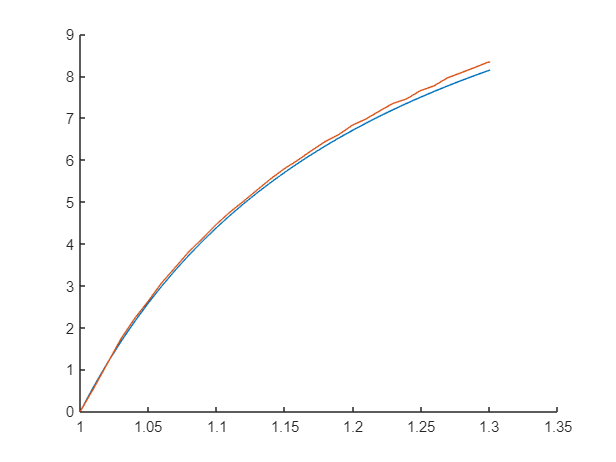

close all
hold on
plot(pt1sim(:,1), pt1sim(:,2));
plot(pt1(:,2), pt1(:,1));
hold off

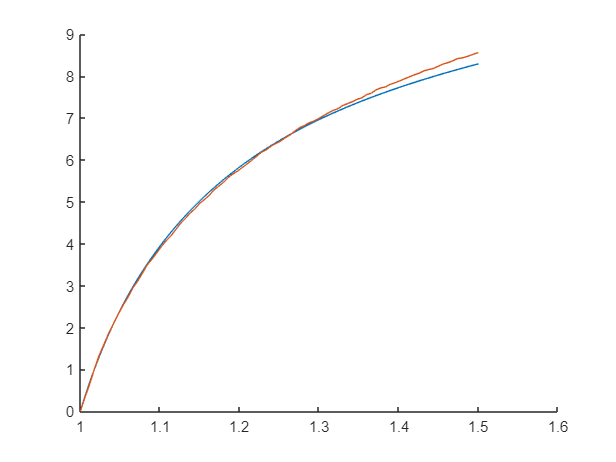

close all
hold on
plot(pt06sim(:,1), pt06sim(:,2));
plot(pt06(:,2), pt06(:,1));
hold off

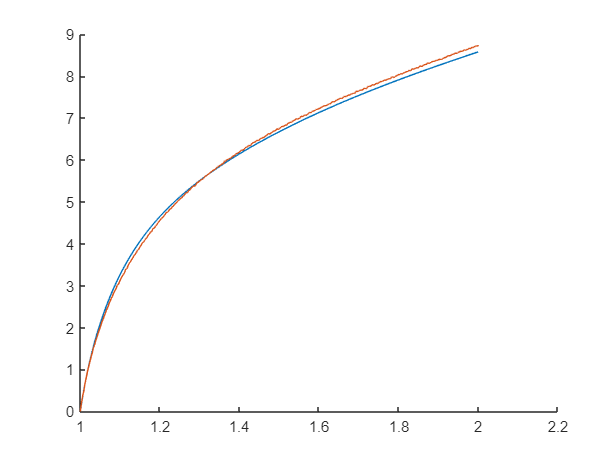

close all
hold on
plot(pt03sim(:,1), pt03sim(:,2));
plot(pt03(:,2), pt03(:,1));
hold off

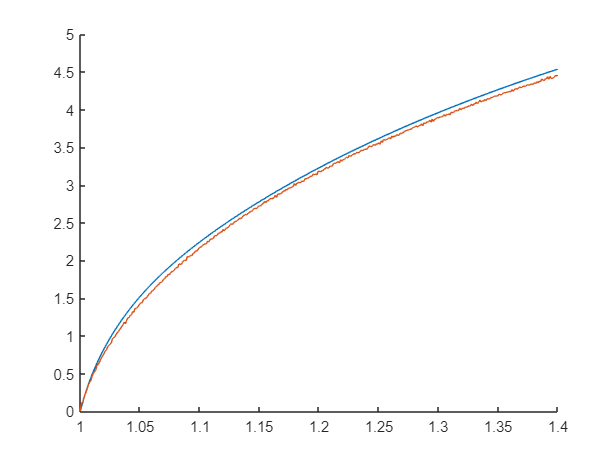

close all
hold on
plot(pt01sim(:,1), pt01sim(:,2));
plot(pt01(:,2), pt01(:,1));
xlim([1, 1.4])
hold off

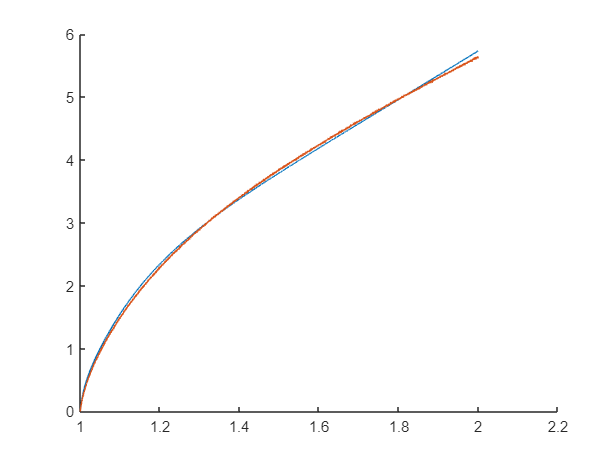

close all
hold on
plot(pt003sim(:,1), pt003sim(:,2));
plot(pt003(:,2), pt003(:,1));
hold off

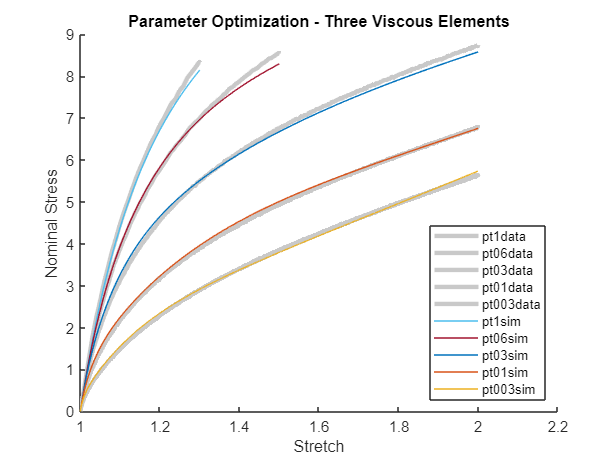

close all
hold on
plot(pt1(:,2), pt1(:,1),'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt06(:,2), pt06(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt03(:,2), pt03(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt01(:,2), pt01(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt003(:,2), pt003(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);

plot(pt1sim(:,1), pt1sim(:,2));
plot(pt06sim(:,1), pt06sim(:,2));
plot(pt03sim(:,1), pt03sim(:,2));
plot(pt01sim(:,1), pt01sim(:,2));
plot(pt003sim(:,1), pt003sim(:,2));
legend('pt1data', 'pt06data', 'pt03data', 'pt01data', 'pt003data', 'pt1sim', 'pt06sim', 'pt03sim', 'pt01sim', 'pt003sim', 'Location', 'southeast')
xlabel('Stretch')
ylabel('Nominal Stress')
title('Parameter Optimization - Three Viscous Elements')

hold off